# **RS-WISP-08-07: Finite burn transfer code**

## **Step 1: Generate Mission Sequence**

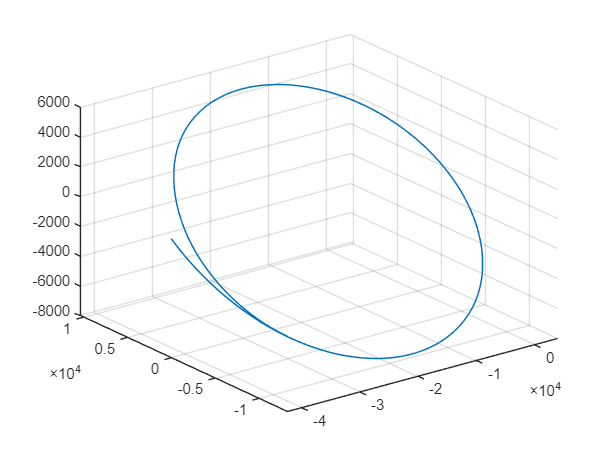

mu = 398600.4415;
r_p = 6378 + 200;
r_a = 6378 + 36000;
inc_initial = 28;

RAAN_initial = 0;
AOP_initial = 0;
TA_initial = 180;

T = 0.2;
I_sp = 1500;
m_0 = 1000;
Thrust_vector = [0,0.1,0]';


% Calculate the semi-major axis and eccentricity of the orbit
a_initial = (r_p + r_a) / 2;
e_initial = (r_a - r_p) / (r_a + r_p);

Orbit_Period = 2*pi*sqrt(a_initial^3/mu);
t_vector = 0:1:Orbit_Period;


initial_Orbit_Parameters.a =  a_initial;
initial_Orbit_Parameters.e =  e_initial;
initial_Orbit_Parameters.i = inc_initial;
initial_Orbit_Parameters.RAAN = 0;
initial_Orbit_Parameters.AOP = 0;
initial_Orbit_Parameters.TA = 180;


[r_matrix, v_matrix, a_vector, e_vector, i_vector, r_p_vector, m_vector, time_vector] = finite_burn_transfer_mission(initial_Orbit_Parameters, T, I_sp, m_0, Thrust_vector, t_vector);



figure;
plot3(r_matrix(:,1), r_matrix(:,2),r_matrix(:,3),'LineWidth',1)
grid on

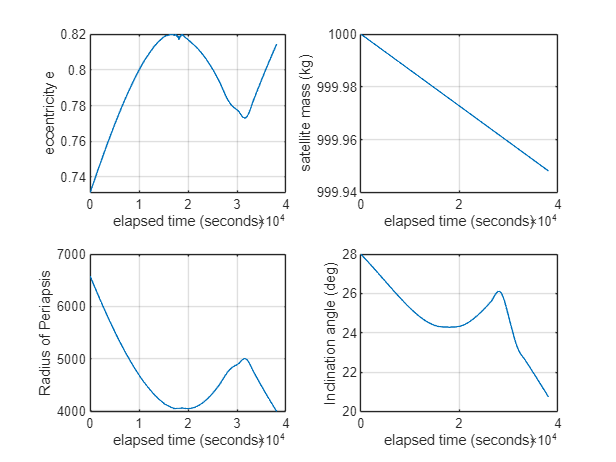


subplot(2,2,1)
plot(time_vector, e_vector,'LineWidth',1)
xlabel('elapsed time (seconds)')
ylabel('eccentricity e')
grid on

subplot(2,2,2)
plot(time_vector, m_vector,'LineWidth',1)
xlabel('elapsed time (seconds)')
ylabel('satellite mass (kg)')
grid on

subplot(2,2,3)
plot(time_vector, r_p_vector,'LineWidth',1)
xlabel('elapsed time (seconds)')
ylabel('Radius of Periapsis')
grid on

subplot(2,2,4)
plot(time_vector, i_vector,'LineWidth',1)
xlabel('elapsed time (seconds)')
ylabel('Inclination angle (deg)')
grid on

function [r_matrix, v_matrix, a_vector, e_vector, i_vector, r_p_vector, m_vector, time_vector] = finite_burn_transfer_mission(initial_Orbit_Parameters, T, I_sp, m_0, Thrust_vector, t_vector)


a_initial = initial_Orbit_Parameters.a;
e_initial = initial_Orbit_Parameters.e;
i_initial = initial_Orbit_Parameters.i;
RAAN_initial = initial_Orbit_Parameters.RAAN;
AOP_initial = initial_Orbit_Parameters.AOP;
TA_initial = initial_Orbit_Parameters.TA;


[r_initial,v_initial] = kepler2ijk_hs(a_initial,e_initial,i_initial,RAAN_initial,AOP_initial,TA_initial);
 X_initial(1:3) = r_initial;
 X_initial(4:6) = v_initial;
 X_initial(7) = m_0;
 T_vec = T * Thrust_vector;
 %odeoptions = odeset('RelTol',1e-10,'AbsTo',1e-20);
 [t,X] = ode45(@(t,X) finite_burn_transfer(t, X, T_vec, I_sp), t_vector, X_initial);

 r_matrix = X(:,1:3);
 v_matrix = X(:,4:6);

 a_vector = zeros(length(t),1);
 e_vector = zeros(length(t),1);
 i_vector = zeros(length(t),1);
 r_p_vector = zeros(length(t),1);
 m_vector = X(:,7);
 time_vector = t_vector;


 for time_index = 1:length(t)
   r = r_matrix(time_index,:)';
   v = v_matrix(time_index,:)';
   [a_temp, e_temp, inc_temp, RAAN_temp, AOP_temp, theta_temp] = ijk2kepler_hs(r,v);
   a_vector(time_index) = a_temp;
   e_vector(time_index) = e_temp;
   i_vector(time_index) = inc_temp;
   r_p_vector(time_index) = a_temp * (1 - e_temp);
 end


end



function dXdt = finite_burn_transfer(t, X, T_vec, I_sp)
  g_0 = 9.8067;
  mu = 398600.4415;
  r_norm = sqrt((X(1)^2 + X(2)^2 + X(3)^2));

  r_vec = [X(1); X(2); X(3)];
  v_vec = [X(4); X(5); X(6)];


  i_hat = r_vec/norm(r_vec);
  k_hat = cross(r_vec, v_vec)/norm(cross(r_vec, v_vec));
  j_hat = cross(k_hat,i_hat)/norm(cross(k_hat,i_hat));
  Q_LVLH_ECI = [i_hat'; j_hat'; k_hat'];

  dXdt =  zeros(7,1);
  dXdt(1) = X(4);
  dXdt(2) = X(5);
  dXdt(3) = X(6);

  dXdt(4) = (-mu/r_norm^3 + T_vec' * Q_LVLH_ECI(:,1)/X(7)/abs(X(1)))*X(1);
  dXdt(5) = (-mu/r_norm^3 + T_vec' * Q_LVLH_ECI(:,2)/X(7)/abs(X(2)))*X(2);
  dXdt(6) = (-mu/r_norm^3 + T_vec' * Q_LVLH_ECI(:,2)/X(7)/abs(X(3)))*X(3);
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                              
  dXdt(7) = -1/I_sp/g_0 * (abs(T_vec(1))+abs(T_vec(2))+abs(T_vec(3)));
end




## Appendix 2: ECI to Keplerian Converter (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;
end